14-Bus: State Estimation

clear all
clc
rng('default');
rng(1);

Tolerance= 0.001;
Count_Max=10;
Count=0; 
Flag=1;

%read in data 
Bus_data = 'Bus data 14 bus.xlsx'

Bus_data = 'Bus data 14 bus.xlsx'

T = readtable(Bus_data);


%P = Pgen - Pload
Real_power= T(1:14, 'RealPower');
P = table2array(Real_power);
%Add white gaussian noise to simulate 'real' measurements 
P = P + 0.05*wgn(14,1, 0);

%Q = Qgen - Qload
Reactive_power= T(1:14, 'ReactivePower');
Q = table2array(Reactive_power);
Q = Q + 0.05*wgn(14,1, 0);

%true voltage values 
Voltage = T(1:14, 'DesiredVoltsPu');
Vx = table2array(Voltage);
 
truev = T(1:14, 'FinalVoltagePu');
V_true = table2array(truev);

%%true angle values 
trueo = T(1:14, 'FinalAngle');
O_true = table2array(trueo);


ii = [1 1 2 2 2 3 4 4 4 5 6 6 6 7 7 9 9 10 12 13];
jj = [2 5 3 4 5 4 5 7 9 6 11 12 13 8 9 10 14 11 13 14];

admittance_fourteen_bus

Solve for 'true' real and reactive power flow values 

x = 1; m =1; %index values 
n = 20; %no. network branches
Pij_true = 0;
Pij_true_col =zeros(20,1);

while x<=n
      Pij_true = V_true(ii(x))^2*G(ii(x),jj(x))-V_true(ii(x))*V_true(jj(x))*(G(ii(x),jj(x))*cos(O_true(ii(x))-O_true(jj(x)))+B(ii(x),jj(x))*sin(O_true(ii(x))-O_true(jj(x))));
      Pij_true_col(m) = Pij_true;      
      x = x+1;
      m = m+1;
end
Pij_true_col;

x = 1; m =1; n = 20; 
Qij_true = 0;
Qij_true_col =zeros(20,1);

while x<=n
      Qij_true = -V_true(ii(x))^2*B(ii(x),jj(x))-V_true(ii(x))*V_true(jj(x))*(G(ii(x),jj(x))*sin(O_true(ii(x))-O_true(jj(x)))-B(ii(x),jj(x))*cos(O_true(ii(x))-O_true(jj(x))));
      Qij_true_col(m) = Qij_true;      
      x = x+1;
      m = m+1;
end
Qij_true_col;

Input 'bad data' here

%P(5) = 5; 
% Q(6) = 5; Pij_true_col(6) = 5; Qij_true_col(6) = 5;

14-bus network (1 slack, 4 PV, 9 PQ)

%initialise phase and voltage values - flat start 
angles = zeros([1 13]); %Bus 2 to 14 
x_new = [angles 1 1 1 1 1 1 1 1 1]'; %9 voltages correponding to 9 PQ buses 


while( Flag==1 && Count < Count_Max)  

Count=Count+1;
O = [0 x_new(1:13)'];
V = [Vx(1) Vx(2) Vx(3) x_new(14) x_new(15) Vx(6) x_new(16) Vx(8) (x_new(17:22))'];


Calculate h(x)

%Real power injection values 
N = 14; %no. busses 
i = 2; %row of admittance matrix
j = 1; %column of admittance matrix 
m= 1; %count for P_list index
P_List =zeros(13,1);
P_inj = 0.0;

while i<=N
     while j<=N
        P_inj = P_inj + V(i)*mag(i,j)*V(j)*cos(O(i)-O(j)-theta(i,j));
        j=j+1;
     end 
        P_List(m) = P_inj;
        P_inj = 0.0;        j = 1;        i=i+1;        m = m+1;
end
P_List;

%Reactive power injection values 
i = 4; j=1; m= 1; %reset index values 
Q_inj = 0.0; Q_List =zeros(11,1); 

while i<=N
    while j<=N
        Q_inj = Q_inj + (V(i)*mag(i,j)*V(j)*sin(O(i)-O(j)-theta(i,j)));
        j=j+1;
    end
        Q_List(m) = Q_inj;
        Q_inj = 0.0;        j = 1;        i=i+1;        m = m+1; 
end

%Delete Qinj values corresponding to VC buses
Q_List=[Q_List(1) Q_List(2) Q_List(4) Q_List(6:11)']';


%Real power flow values 
x = 1; n = 20; 
Pij = 0; Pij_col =zeros(20,1);

while x<=n
      Pij = V(ii(x))^2*G(ii(x),jj(x))-V(ii(x))*V(jj(x))*(G(ii(x),jj(x))*cos(O(ii(x))-O(jj(x)))+B(ii(x),jj(x))*sin(O(ii(x))-O(jj(x))));
      Pij_col(x) = Pij;      
      x = x+1;     
end
Pij_col;

%Reactive power flow values 
x = 1; n = 20; 
Qij = 0; Qij_col =zeros(20,1);

while x<=n
      Qij = -V(ii(x))^2*B(ii(x),jj(x))-V(ii(x))*V(jj(x))*(G(ii(x),jj(x))*sin(O(ii(x))-O(jj(x)))-B(ii(x),jj(x))*cos(O(ii(x))-O(jj(x))));
      Qij_col(x) = Qij;      
      x = x+1;
end
Qij_col;

%Measurement function 
h = [P_List; Pij_col; Q_List; Qij_col];


Jacobian Matrix

%first section of Jacobian dP/dO
i = 2; %index for P [P2-P14]
k = 2; %index of angle [O2-O14]
j=1; %index 
N = 14; %no. busses 
P_O_col =zeros(169,1);
m = 1;
P_O=0.0;
while k<=N    
    while i<=N
        if (i==k)
            while j<=N
                P_O = P_O-(V(i)*V(j)*mag(i,j)*sin(O(i)-O(j)-theta(i,j)));
                j = j+1;
            end
            P_O = P_O + (V(i)*mag(i,i)*V(i)*sin(O(i)-O(i)-theta(i,i)));
            P_O_col(m) = P_O; j=1; P_O = 0.0;
        elseif (i~=k)
             P_O = V(i)*V(k)*mag(i,k)*sin(O(i)-O(k)-theta(i,k));
             P_O_col(m) = P_O;             P_O = 0.0;
        end
       i = i+1;        m = m+1;
    end 
   k = k+1;    i=2;
end
P_O_col; 
P_O_reshape = reshape(P_O_col,[13,13]);


%second section of Jacobian - dQ/dO

i = 4; %index for [Q4-Q9] 
k = 2; %index of angle [O2-O9] 
j=1; %index for count in summation
N = 14; %no. busses 
m =1;
Q_O_col = zeros(143,1); Q_O=0.0;

while k<=N    
    while i<=N
        if (i==k)
            while j<=N
                Q_O = Q_O +V(i)*mag(i,j)*V(j)*cos(O(i)-O(j)-theta(i,j));
                j = j+1;
            end
            Q_O = Q_O-(V(i)*mag(i,i)*V(i)*cos(O(i)-O(i)-theta(i,i)));
            Q_O_col(m) = Q_O;             j=1;             Q_O = 0.0;
        elseif (i~=k)
             Q_O = -V(i)*V(k)*mag(i,k)*cos(O(i)-O(k)-theta(i,k));
             Q_O_col(m) = Q_O;              Q_O = 0.0;
        end
       i = i+1;       m=m+1;
    end  
   k = k+1;   i=4;
end
Q_O_col; 
Q_O_reshape = reshape(Q_O_col,[11,13]);
Q_O_reshape(3,:)=[]; %discard rows correponding to VC buses
Q_O_reshape(4,:)=[]; 
Q_O_reshape;


%third section of Jacobian - dP/dV

i = 2; %index for P [P2-P57]
k = 4; %index of voltage [V4-V57]
j=1; %index 
N = 14; %no. busses 
P_V_col = zeros(143,1);
m=1; P_V=0.0;

while k<=N    
    while i<=N
        if (i==k)
            while j<=N
                P_V = P_V +mag(i,j)*abs(V(j))*cos(O(i)-O(j)-theta(i,j));
                j = j+1;
            end
            P_V = P_V+V(i)*mag(i,i)*cos(theta(i,i));
            P_V_col(m) = P_V;
            P_V = 0.0;             j=1; 
        elseif (i~=k)
             P_V = V(i)*mag(i,k)*cos(O(i)-O(k)-theta(i,k));
             P_V_col(m) = P_V;              P_V = 0.0;
        end
       i = i+1;        m = m+1;       
    end 
   k = k+1;    i=2;
end
P_V_col; 
P_V_reshape = reshape(P_V_col,[13,11]);
P_V_reshape(:,3)=[]; %discard columns corresponding to VC buses 
P_V_reshape(:,4)=[];
P_V_reshape;


%fourth section of Jacobian - dQ/dV

i = 4; %index for Q [Q4 - Q57]
k = 4; %index for voltage [V4-V57]
j=1; %index
N = 14; %no. busses 
Q_V_col = zeros(121,1);
m=1; Q_V=0.0;

while k<=N    
    while i<=N
        if (i==k)
            while j<=N
                Q_V = Q_V +(mag(i,j)*V(j)*sin(O(i)-O(j)-theta(i,j)));
                j = j+1;
            end
            Q_V = Q_V-V(i)*mag(i,i)*sin(theta(i,i));
            Q_V_col(m) = Q_V;             Q_V = 0.0;             j=1; 
        elseif (i~=k)
             Q_V = V(i)*mag(i,k)*sin(O(i)-O(k)-theta(i,k));
             Q_V_col(m) = Q_V;              Q_V = 0.0;
        end
       i = i+1;        m = m+1;
    end 
   k = k+1;    i=4;
end
Q_V_col; 
Q_V_reshape = reshape(Q_V_col,[11,11]);
Q_V_reshape(3,:)=[]; %discard rows and cols corresponding to VC buses 
Q_V_reshape(4,:)=[];
Q_V_reshape(:,3)=[];
Q_V_reshape(:,4)=[];
Q_V_reshape;

%fourth section of Jacobian - dPF/dO
x = 1; k = 2; %indexes
N=14; % no. busses
n = 20; %no. measurements 
PF_O_col =zeros(260,1);
m = 1; PF_O=0.0;
while x<=n
while k<=N    
    if (ii(x)==k)
            PF_O = V(ii(x))*V(jj(x))*(G(ii(x),jj(x))*sin(O(ii(x))-O(jj(x)))-B(ii(x),jj(x))*cos(O(ii(x))-O(jj(x)))); 
            PF_O_col(m) = PF_O;             PF_O = 0.0;
    elseif (jj(x)==k)
             PF_O = -V(ii(x))*V(jj(x))*(G(ii(x),jj(x))*sin(O(ii(x))-O(jj(x)))-B(ii(x),jj(x))*cos(O(ii(x))-O(jj(x))));
             PF_O_col(m) = PF_O;              PF_O = 0.0;
    else
             PF_O = 0;              PF_O_col(m) = PF_O;
    end 
    m = m+1;     k = k+1;
end
k = 2; x = x+1;
end
PF_O_col; 
PF_O_reshape = reshape(PF_O_col,[13,20]);
PF_O_reshape = transpose(PF_O_reshape);

%sixth section of Jacobian - dPF/dV
x = 1; k = 4; 
N=14; % no. busses
n = 20; %no. measurements
PF_V_col =zeros(220,1); 
m = 1; PF_V=0.0;

while x<=n
while k<=N    
    if (ii(x)==k)
            PF_V = -V(jj(x))*(G(ii(x),jj(x))*cos(O(ii(x))-O(jj(x)))+B(ii(x),jj(x))*sin(O(ii(x))-O(jj(x))))+2*(G(ii(x),jj(x)))*V(ii(x));
            PF_V_col(m) = PF_V;            PF_V = 0.0;
    elseif (jj(x)==k)
             PF_V = -V(ii(x))*(G(ii(x),jj(x))*cos(O(ii(x))-O(jj(x)))+B(ii(x),jj(x))*sin(O(ii(x))-O(jj(x))));
             PF_V_col(m) = PF_V;              PF_V = 0.0;
    
    else
             PF_V = 0;              PF_V_col(m) = PF_V;
    end 
    m = m+1;     k = k+1;
end
k = 4; x = x+1;
end
PF_V_col; 
PF_V_reshape = reshape(PF_V_col,[11,20]);
PF_V_reshape = transpose(PF_V_reshape);
PF_V_reshape(:,3)=[];
PF_V_reshape(:,4)=[];
PF_V_reshape;

%seventh section of Jacobian - dQF/dO
x = 1; k = 2;
N=14; % no. busses
n = 20; %no. measurements 
QF_O_col =zeros(260,1);
m = 1; QF_O=0.0;
while x<=n
while k<=N    
    if (ii(x)==k)
            QF_O = -V(ii(x))*V(jj(x))*(G(ii(x),jj(x))*cos(O(ii(x))-O(jj(x)))+B(ii(x),jj(x))*sin(O(ii(x))-O(jj(x))));
            QF_O_col(m) = QF_O;             QF_O = 0.0;
    elseif (jj(x)==k)
             QF_O = V(ii(x))*V(jj(x))*(G(ii(x),jj(x))*cos(O(ii(x))-O(jj(x)))+B(ii(x),jj(x))*sin(O(ii(x))-O(jj(x))));
             QF_O_col(m) = QF_O;              QF_O = 0.0;
    
    else
             QF_O = 0;              QF_O_col(m) = QF_O;
    end 
    m = m+1;     k = k+1;
end
k = 2; x = x+1;
end
QF_O_col; 
QF_O_reshape = reshape(QF_O_col,[13,20]);
QF_O_reshape = transpose(QF_O_reshape);

%eighth section of Jacobian - dQF/dV
x = 1; k = 4; %index of angle [V4-V14]
N=14; % no. busses
n = 20; %no. measurements 
QF_V_col =zeros(220,1); 
m = 1; QF_V=0.0;
while x<=n
while k<=N    
    if (ii(x)==k)
            QF_V = -V(jj(x))*(G(ii(x),jj(x))*sin(O(ii(x))-O(jj(x)))-B(ii(x),jj(x))*cos(O(ii(x))-O(jj(x))))-2*(B(ii(x),jj(x)))*V(ii(x));
            QF_V_col(m) = QF_V;             QF_V = 0.0;
    elseif (jj(x)==k)
             QF_V = -V(ii(x))*(G(ii(x),jj(x))*sin(O(ii(x))-O(jj(x)))-B(ii(x),jj(x))*cos(O(ii(x))-O(jj(x))));
             QF_V_col(m) = QF_V;              QF_V = 0.0;
    
    else
             QF_V = 0;              QF_V_col(m) = QF_V;
    end 
    m = m+1;     k = k+1;
end
k = 4; x = x+1;
end
QF_V_col; 
QF_V_reshape = reshape(QF_V_col,[11,20]);
QF_V_reshape = transpose(QF_V_reshape);
QF_V_reshape(:,3)=[];
QF_V_reshape(:,4)=[];
QF_V_reshape;

J = [P_O_reshape P_V_reshape; PF_O_reshape PF_V_reshape; Q_O_reshape Q_V_reshape; QF_O_reshape QF_V_reshape];


Covariance Matrix

e = 3*10^(-2);
error = repmat(e,1, 62);
R = diag(error);

Gain Matrix

Gain = J'*R^(-1)*J;

Measured Values

P_meas = P(2:14);
Q_req = Q(4:14);
Q_meas = [Q_req(1:2)' Q_req(4)' Q_req(6:11)']';

%observation vector 
y = [P_meas; Pij_true_col; Q_meas; Qij_true_col];


Update state vector

delta_x = Gain^(-1)*J'*R^(-1)*(y-h);
x_new = x_new + delta_x;

%Max mismatch from old state to new state
Mismatch = max(abs(delta_x));
 

Compare mismatch to tolerance value

if (Mismatch> Tolerance)
Flag = 1;
else
    Flag = 0;
end
end

%Change phases from rad to degrees 
angles_deg = rad2deg(x_new(1:13));

%Print final states [phases voltages]
final= [0 angles_deg' V(1) V(2) V(3) x_new(14:15)' V(6) x_new(16)' V(8) (x_new(17:22))']

final =          0   -4.9777  -12.9417  -10.4578   -8.9268  -14.4135  -13.3861  -13.2789  -14.8967  -15.0943  -14.8499  -14.9046  -15.3829  -16.0213    1.0600    1.0450    1.0100    1.0151    1.0179    1.0700    1.0601    1.0900    1.0534    1.0522    1.0505    1.0540    1.0485    1.0449




%Print max mismatch between prev and current state
Final_tolerance = Mismatch

Final_tolerance = 1.2003e-05


%print no. iterations required 
Count

Count = 3

Plots 

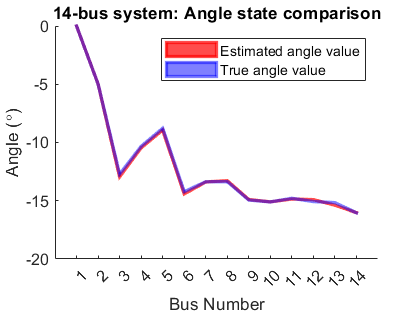

x_axis = linspace(1, 14,14);
y1 = final(1:14);
y2 = rad2deg(O_true);

figure
hold on

p1 = patchline(x_axis,y1, 'facecolor',[1 0 0],'edgecolor',[1 0 0], 'LineWidth', 2, 'edgealpha',0.7, 'facealpha',0.7);
p2 = patchline(x_axis,y2, 'facecolor',[0 0 1],'edgecolor',[0 0 1], 'LineWidth', 2, 'edgealpha',0.5, 'facealpha',0.5);

xticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14]);
title('14-bus system: Angle state comparison');
xlabel('Bus number'); 
ylabel('Angle (\circ)');
legend({'Estimated angle value', 'True angle value'}, 'Location', 'northeast' )
hold off

%title("Without error detection:", "Angle comparison when P_{inj} = 5pu at Bus 5")
xlabel("Bus Number")

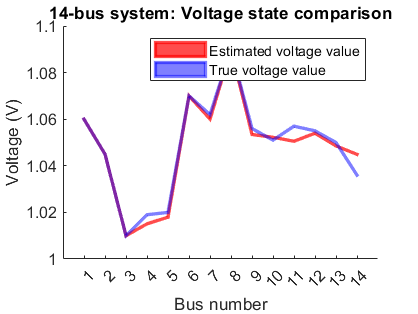


y1 = final(15:28);
y2 = V_true;

figure
hold on

p1 = patchline(x_axis,y1, 'facecolor',[1 0 0],'edgecolor',[1 0 0], 'LineWidth', 2, 'edgealpha',0.7, 'facealpha',0.7);
p2 = patchline(x_axis,y2, 'facecolor',[0 0 1],'edgecolor',[0 0 1], 'LineWidth', 2, 'edgealpha',0.5, 'facealpha',0.5);

xticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14]);
%ylim([1 1.12])
title('14-bus system: Voltage state comparison');
%title("Without error detection:", "Voltage comparison when P_{inj} = 5pu at Bus 5");
xlabel('Bus number'); 
ylabel('Voltage (V)');
legend({'Estimated voltage value', 'True voltage value'}, 'Location', 'northeast')

hold off